clc;
clear;

% Problem #1
% - Assuming Ev is at 0, Ec = Eg
% - I did part e) before d) so that I could obtain a more accurate
% peak emission wavelength for the linewidth calculation, instead of
% estimating
Ec = 1.4; % Energy of conduction band in eV
lambda = .8*10^-6:.0001*10^-6:1*10^-6;
% lambda0 = 850*10^-9; % typical wavelength of light emitted from GaAs LED
k = 8.6173*10^-5 % Boltzmann's constant, in terms of eV

k = 8.6173e-05

T = 350; % Temperature in kelvin
h = 4.136*10^-15; % Plank's constant in eV/Hz
c = 3*10^8; % speed of light
E = h.*(c./lambda) % Energy in eV

E =     1.5510    1.5508    1.5506    1.5504    1.5502    1.5500    1.5498    1.5496    1.5495    1.5493    1.5491    1.5489    1.5487    1.5485    1.5483    1.5481    1.5479    1.5477    1.5475    1.5473    1.5471    1.5469    1.5467    1.5466    1.5464    1.5462    1.5460    1.5458    1.5456    1.5454    1.5452    1.5450    1.5448    1.5446    1.5444    1.5442    1.5441    1.5439    1.5437    1.5435    1.5433    1.5431    1.5429    1.5427    1.5425    1.5423    1.5421    1.5419    1.5417    1.5416


g = (E-Ec).^.5

g =    0.3886 + 0.0000i   0.3883 + 0.0000i   0.3881 + 0.0000i   0.3878 + 0.0000i   0.3876 + 0.0000i   0.3873 + 0.0000i   0.3871 + 0.0000i   0.3868 + 0.0000i   0.3866 + 0.0000i   0.3863 + 0.0000i   0.3861 + 0.0000i   0.3858 + 0.0000i   0.3856 + 0.0000i   0.3853 + 0.0000i   0.3851 + 0.0000i   0.3848 + 0.0000i   0.3846 + 0.0000i   0.3843 + 0.0000i   0.3841 + 0.0000i   0.3838 + 0.0000i   0.3836 + 0.0000i   0.3833 + 0.0000i   0.3831 + 0.0000i   0.3828 + 0.0000i   0.3826 + 0.0000i   0.3823 + 0.0000i   0.3821 + 0.0000i   0.3818 + 0.0000i   0.3816 + 0.0000i   0.3813 + 0.0000i   0.3811 + 0.0000i   0.3808 + 0.0000i   0.3806 + 0.0000i   0.3803 + 0.0000i   0.3800 + 0.0000i   0.3798 + 0.0000i   0.3795 + 0.0000i   0.3793 + 0.0000i   0.3790 + 0.0000i   0.3788 + 0.0000i   0.3785 + 0.0000i   0.3783 + 0.0000i   0.3780 + 0.0000i   0.3778 + 0.0000i   0.3775 + 0.0000i   0.3773 + 0.0000i   0.3770 + 0.0000i   0.3768 + 0.0000i   0.3765 + 0.0000i   0.3762 + 0.0000i


f = exp((-1.*(E-Ec)))

f =     0.8598    0.8600    0.8602    0.8603    0.8605    0.8607    0.8608    0.8610    0.8612    0.8613    0.8615    0.8617    0.8618    0.8620    0.8622    0.8623    0.8625    0.8627    0.8628    0.8630    0.8632    0.8633    0.8635    0.8637    0.8638    0.8640    0.8642    0.8643    0.8645    0.8647    0.8648    0.8650    0.8652    0.8653    0.8655    0.8657    0.8658    0.8660    0.8662    0.8663    0.8665    0.8667    0.8668    0.8670    0.8672    0.8673    0.8675    0.8677    0.8678    0.8680


n = g.*f

n =    0.3341 + 0.0000i   0.3340 + 0.0000i   0.3338 + 0.0000i   0.3337 + 0.0000i   0.3335 + 0.0000i   0.3334 + 0.0000i   0.3332 + 0.0000i   0.3331 + 0.0000i   0.3329 + 0.0000i   0.3328 + 0.0000i   0.3326 + 0.0000i   0.3325 + 0.0000i   0.3323 + 0.0000i   0.3322 + 0.0000i   0.3320 + 0.0000i   0.3319 + 0.0000i   0.3317 + 0.0000i   0.3316 + 0.0000i   0.3314 + 0.0000i   0.3313 + 0.0000i   0.3311 + 0.0000i   0.3309 + 0.0000i   0.3308 + 0.0000i   0.3306 + 0.0000i   0.3305 + 0.0000i   0.3303 + 0.0000i   0.3302 + 0.0000i   0.3300 + 0.0000i   0.3299 + 0.0000i   0.3297 + 0.0000i   0.3296 + 0.0000i   0.3294 + 0.0000i   0.3292 + 0.0000i   0.3291 + 0.0000i   0.3289 + 0.0000i   0.3288 + 0.0000i   0.3286 + 0.0000i   0.3285 + 0.0000i   0.3283 + 0.0000i   0.3282 + 0.0000i   0.3280 + 0.0000i   0.3278 + 0.0000i   0.3277 + 0.0000i   0.3275 + 0.0000i   0.3274 + 0.0000i   0.3272 + 0.0000i   0.3271 + 0.0000i   0.3269 + 0.0000i   0.3267 + 0.0000i   0.3266 + 0.0000i


v0 = (1.4 + .5*k*T)/h * (10^-12) % v0 in THz

v0 = 342.1374

lambda0 = c/v0

lambda0 = 8.7684e+05

lw = ((lambda0^2)/(h*c))*3*k*T % FWHM linewidth for lambda0 found in part e)

lw = 5.6066e+16

% Plotting g(E), f(E), and n(E)
% Part a)
plot(E,g)

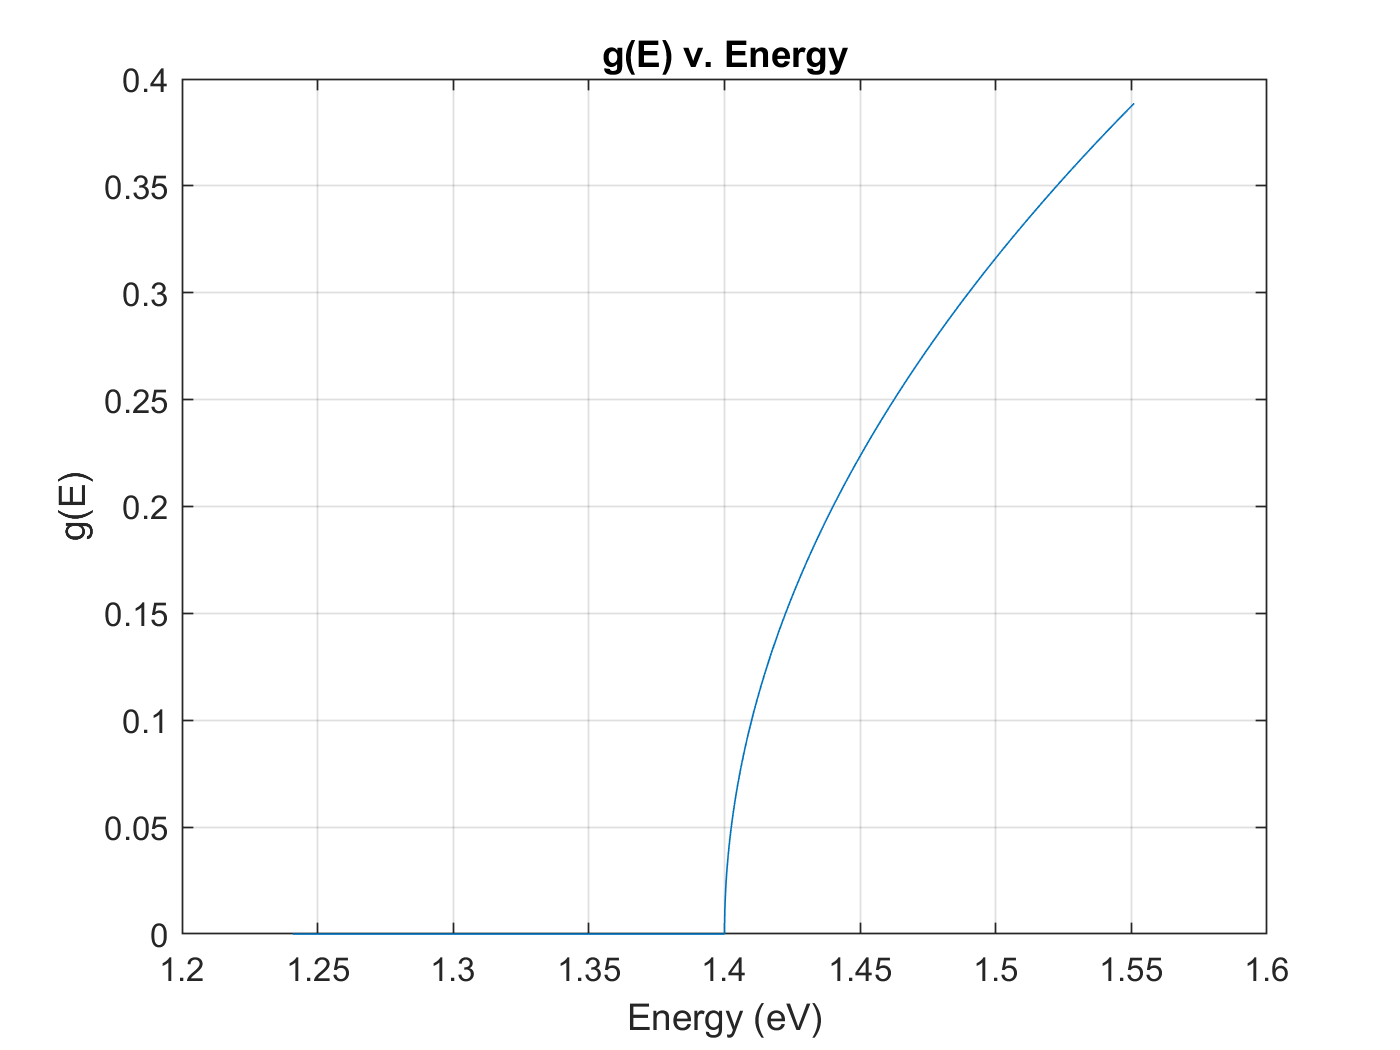

title('g(E) v. Energy')
xlabel('Energy (eV)')
ylabel('g(E)');
grid on;

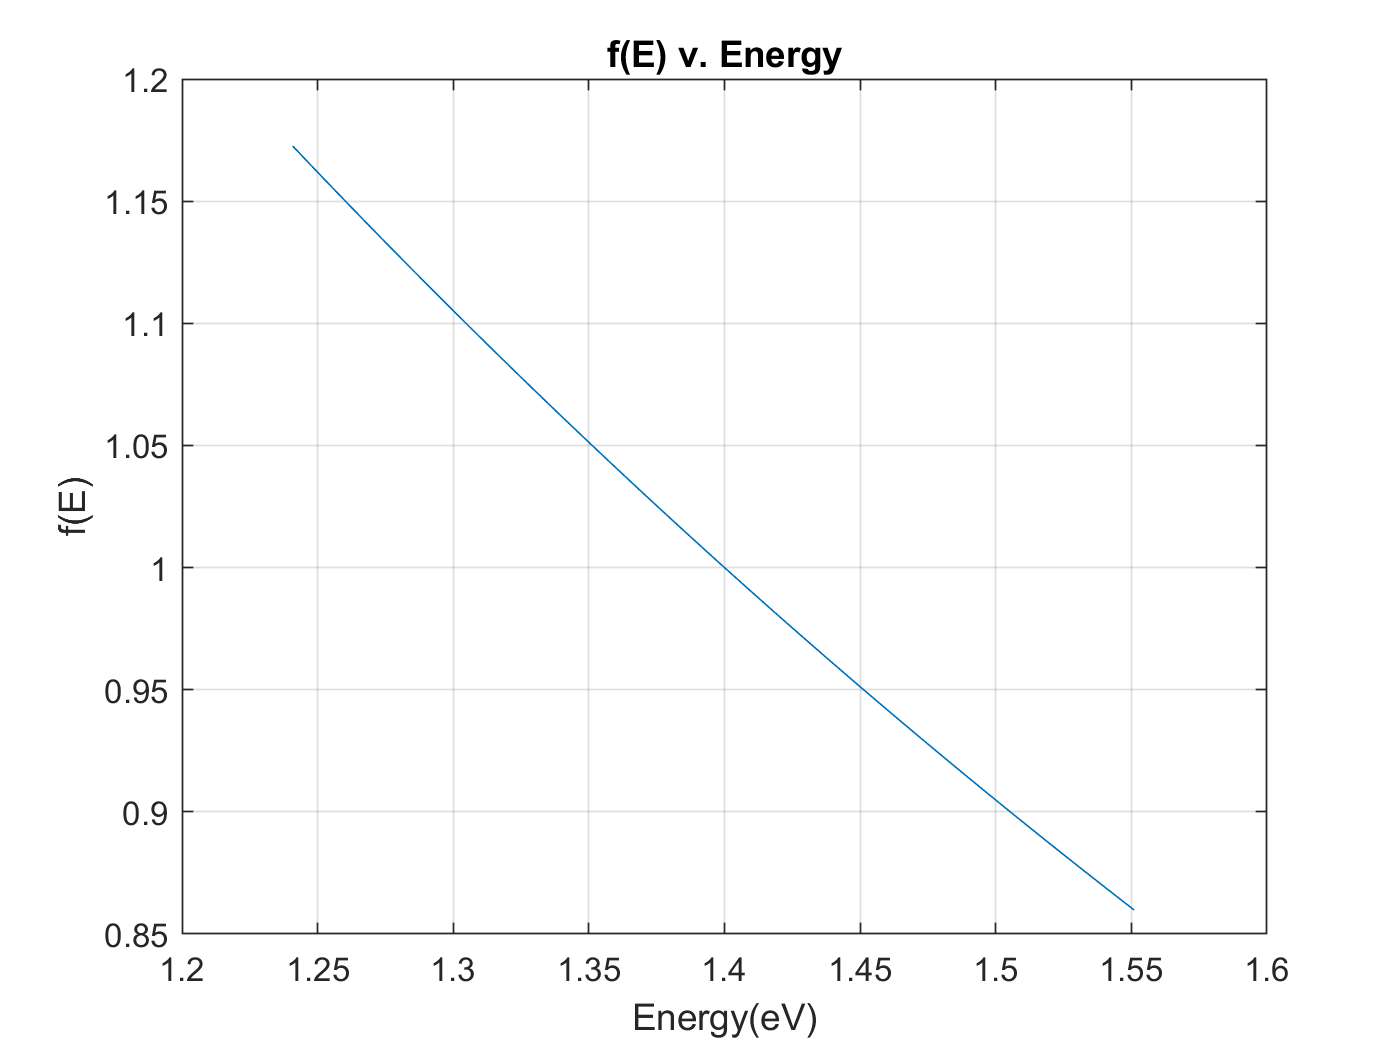


% Part b)
plot(E,f);
title('f(E) v. Energy')
xlabel('Energy(eV)');
ylabel('f(E)');
grid on;


%part c)
plot(E,n);

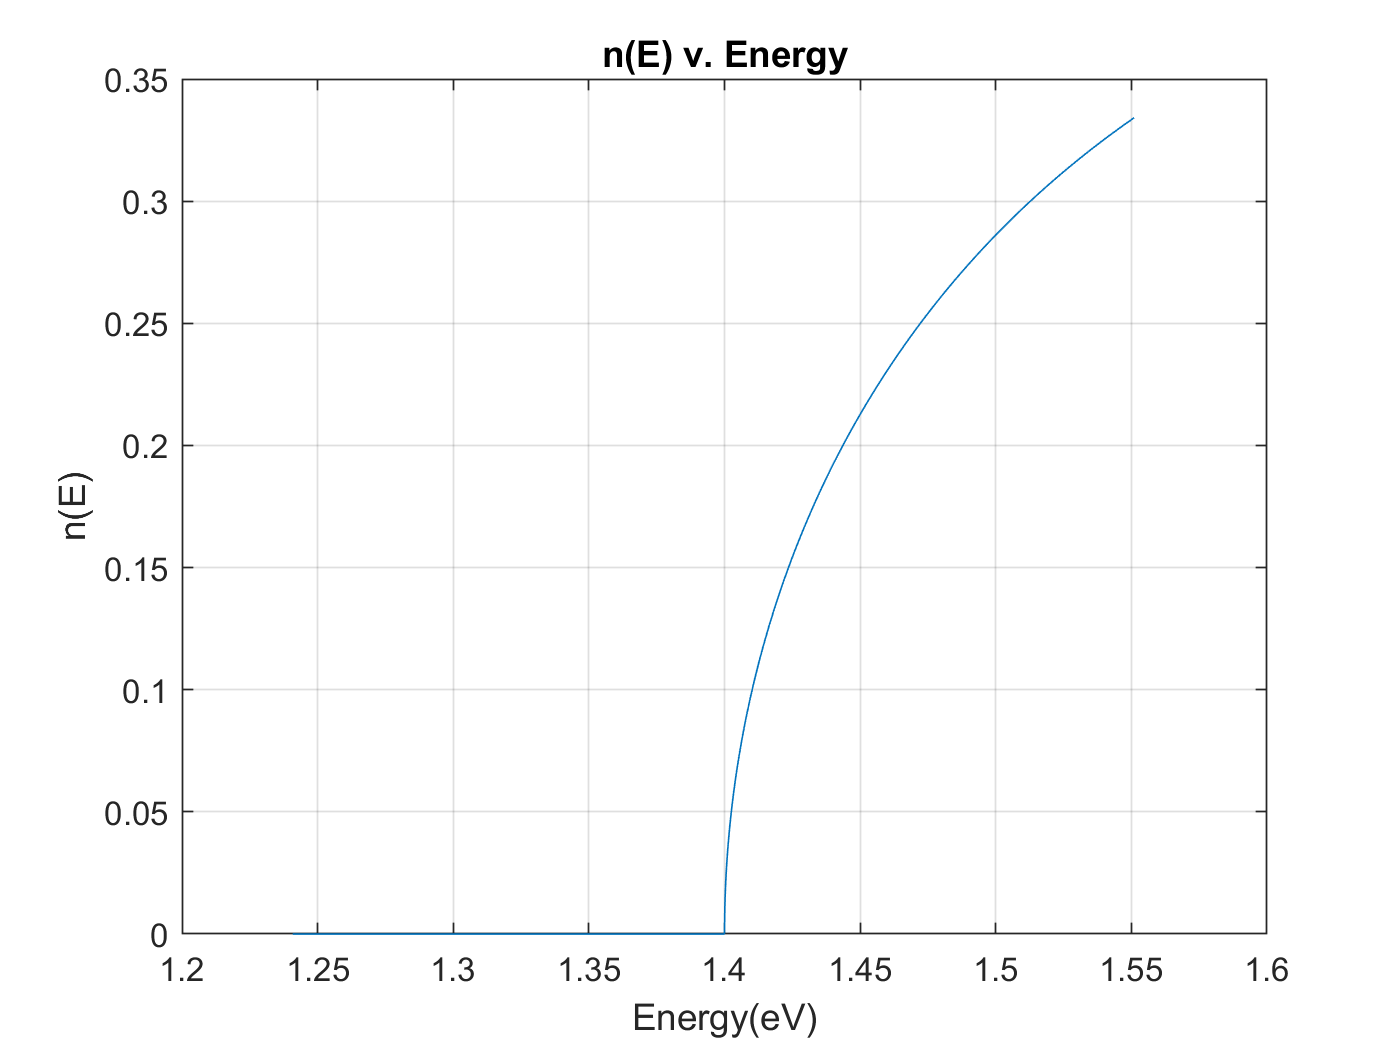

title('n(E) v. Energy')
xlabel('Energy(eV)')
ylabel('n(E)')
grid on;


% Problem #2
A1 = .696749;
A2 = .408218;
A3 = .890815;

C1S = .0690660*10^(-6);
C2S = .115662*10^(-6);
C3S = 9.900559*10^(-6);

R = .95;
L = 500*10^-6

L = 5.0000e-04

% Using refractive index eq. (Sellmeier) for SiO2 from Project 1 to obtain
% intensity in FP cavity
n_SiO2 = sqrt(1+((A1*(lambda.^2))./(lambda.^2-C1S^2)+((A2*(lambda.^2))./(lambda.^2-C2S^2)))+((A3*(lambda.^2))./(lambda.^2-C3S^2)));
mpi = (2*n_SiO2.*L*pi)./lambda;

I = 1./((1-R)^2 + 4*R*sin(mpi).^2);

% Part c)
lambdaR = 870*10^-9; % given wavelength for resonance
% Use Sellmeier Eq. again to find refractive index of cavity given 870 nm
% wavelength
n = sqrt(1+((A1*(lambdaR.^2))./(lambdaR.^2-C1S^2)+((A2*(lambdaR.^2))./(lambdaR.^2-C2S^2)))+((A3*(lambdaR.^2))./(lambdaR.^2-C3S^2)));
m = 2*n*L/lambdaR % closest mode, m, is 1670 

m = 1.6696e+03

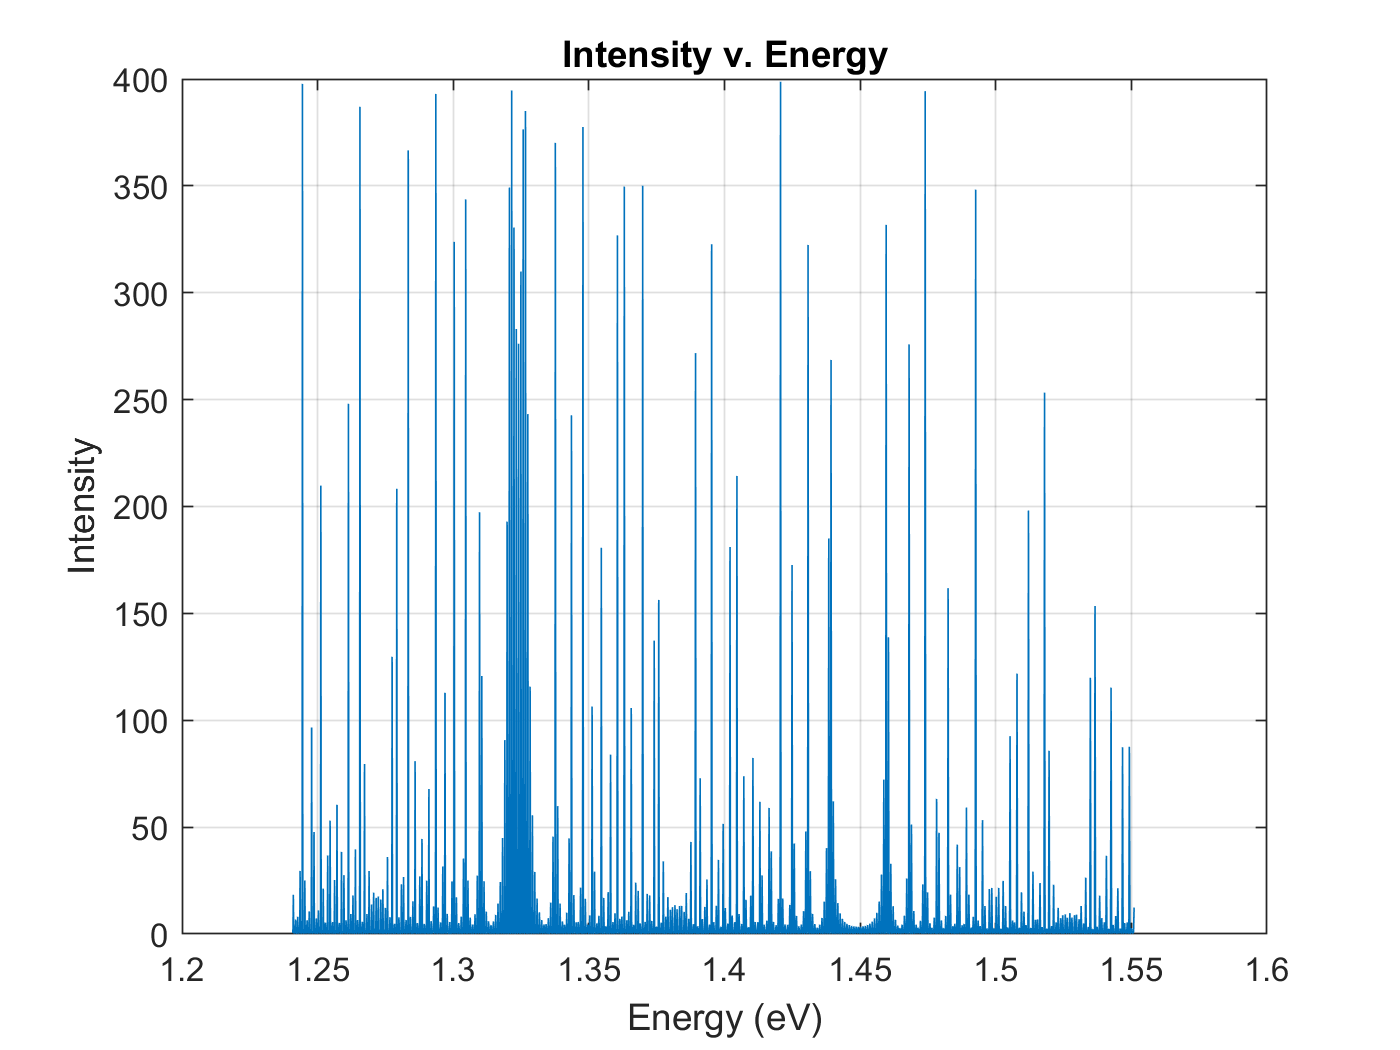


% Part a)
plot(E,I)
xlabel('Energy (eV)')
ylabel('Intensity')
title('Intensity v. Energy')
grid on

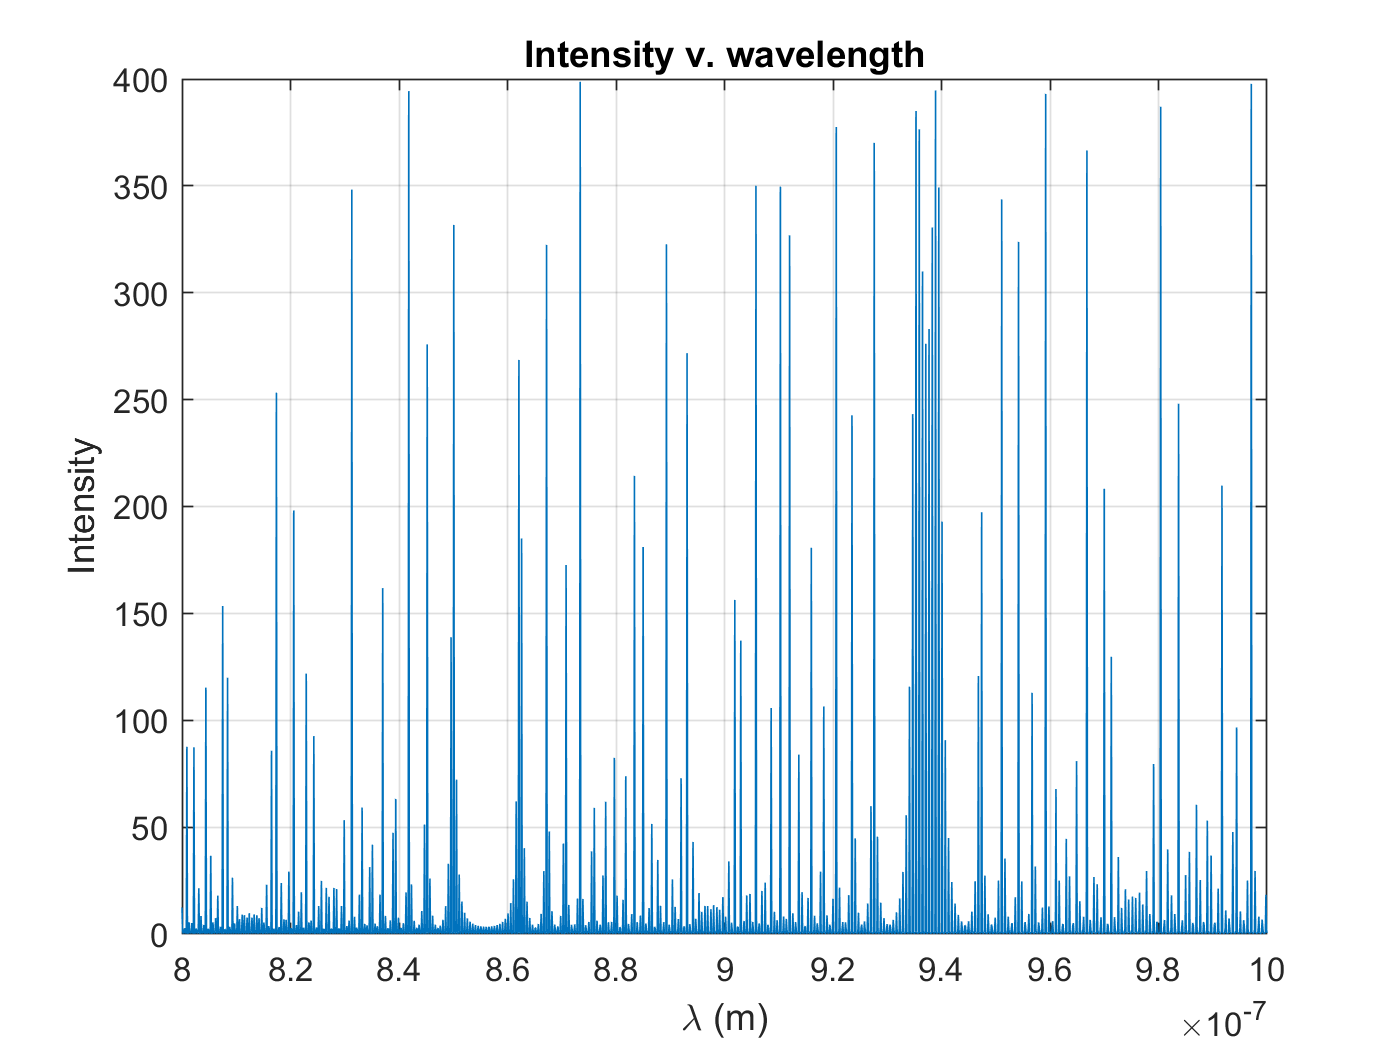


%Part b)
plot(lambda,I)
title('Intensity v. wavelength')
xlabel('\lambda (m)')
ylabel('Intensity')
grid on


% Given the lack of coherent shape for the I v. Eg and I v. lambda graphs,
% I decided to experiment with other wavelength ranges, specifically that
% used for Project 1 (1.5 - 1.53 microns).  It appears this range shows a
% response much closer to that of Project 1, with repeated peaks of a
% certain intensity (little to no variation).  Thus, I conclude for this
% particular problem that the rapid fluctuations in intensity are due to
% the wavelength range of .8 - 1.0 microns


% Problem #3
% Varshni Consants
A = 5.41*10^-4 % in eV/K

A = 5.4100e-04

B = 204; % in K
Eg0 = 1.519; % GaAs Eg at 0 K
T = 298:398;

% Part a)
Eg = Eg0 - ((A*T.^2)./(B+T))

Eg =     1.4233    1.4228    1.4224    1.4219    1.4215    1.4210    1.4206    1.4201    1.4197    1.4192    1.4188    1.4183    1.4179    1.4174    1.4169    1.4165    1.4160    1.4156    1.4151    1.4147    1.4142    1.4137    1.4133    1.4128    1.4124    1.4119    1.4114    1.4110    1.4105    1.4101    1.4096    1.4091    1.4087    1.4082    1.4077    1.4073    1.4068    1.4064    1.4059    1.4054    1.4050    1.4045    1.4040    1.4036    1.4031    1.4026    1.4022    1.4017    1.4012    1.4008


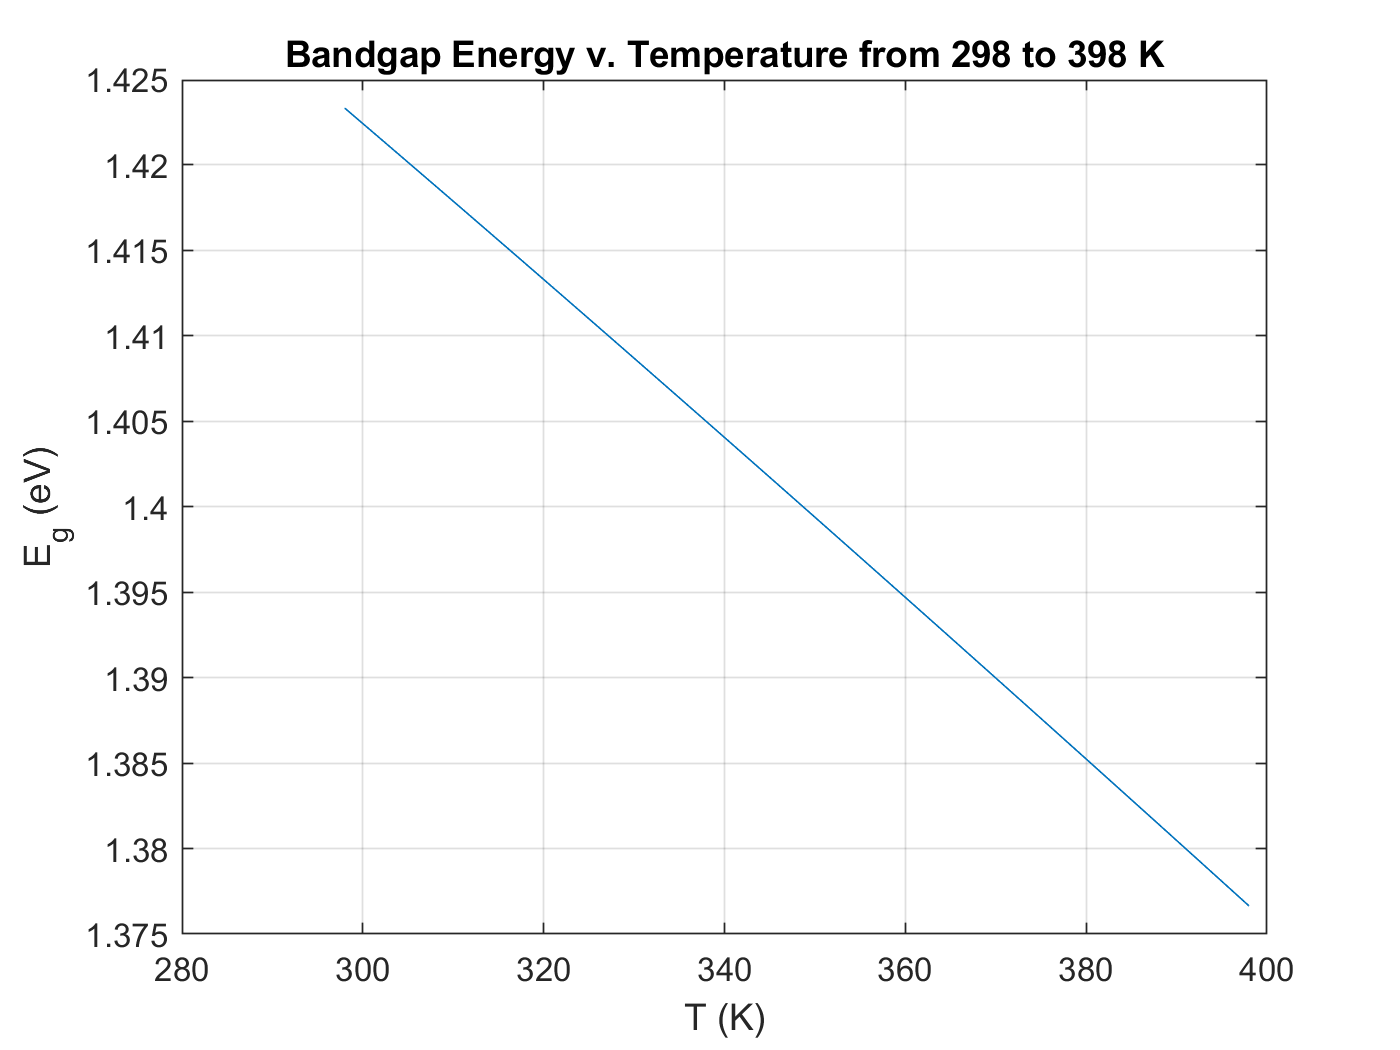

plot(T,Eg)
xlabel('T (K)')
ylabel('E_g (eV)')
title('Bandgap Energy v. Temperature from 298 to 398 K')
grid on;


% Part b)
% - Photon Energy for this part is equal to Bandgap Energy
lambdaBg = (h*c)./Eg % wavelength corresponding to bandgap energy

lambdaBg = 	1.0e+-6 *

    0.8718    0.8721    0.8723    0.8726    0.8729    0.8732    0.8734    0.8737    0.8740    0.8743    0.8746    0.8748    0.8751    0.8754    0.8757    0.8760    0.8763    0.8765    0.8768    0.8771    0.8774    0.8777    0.8780    0.8782    0.8785    0.8788    0.8791    0.8794    0.8797    0.8800    0.8803    0.8805    0.8808    0.8811    0.8814    0.8817    0.8820    0.8823    0.8826    0.8829    0.8832    0.8834    0.8837    0.8840    0.8843    0.8846    0.8849    0.8852    0.8855    0.8858


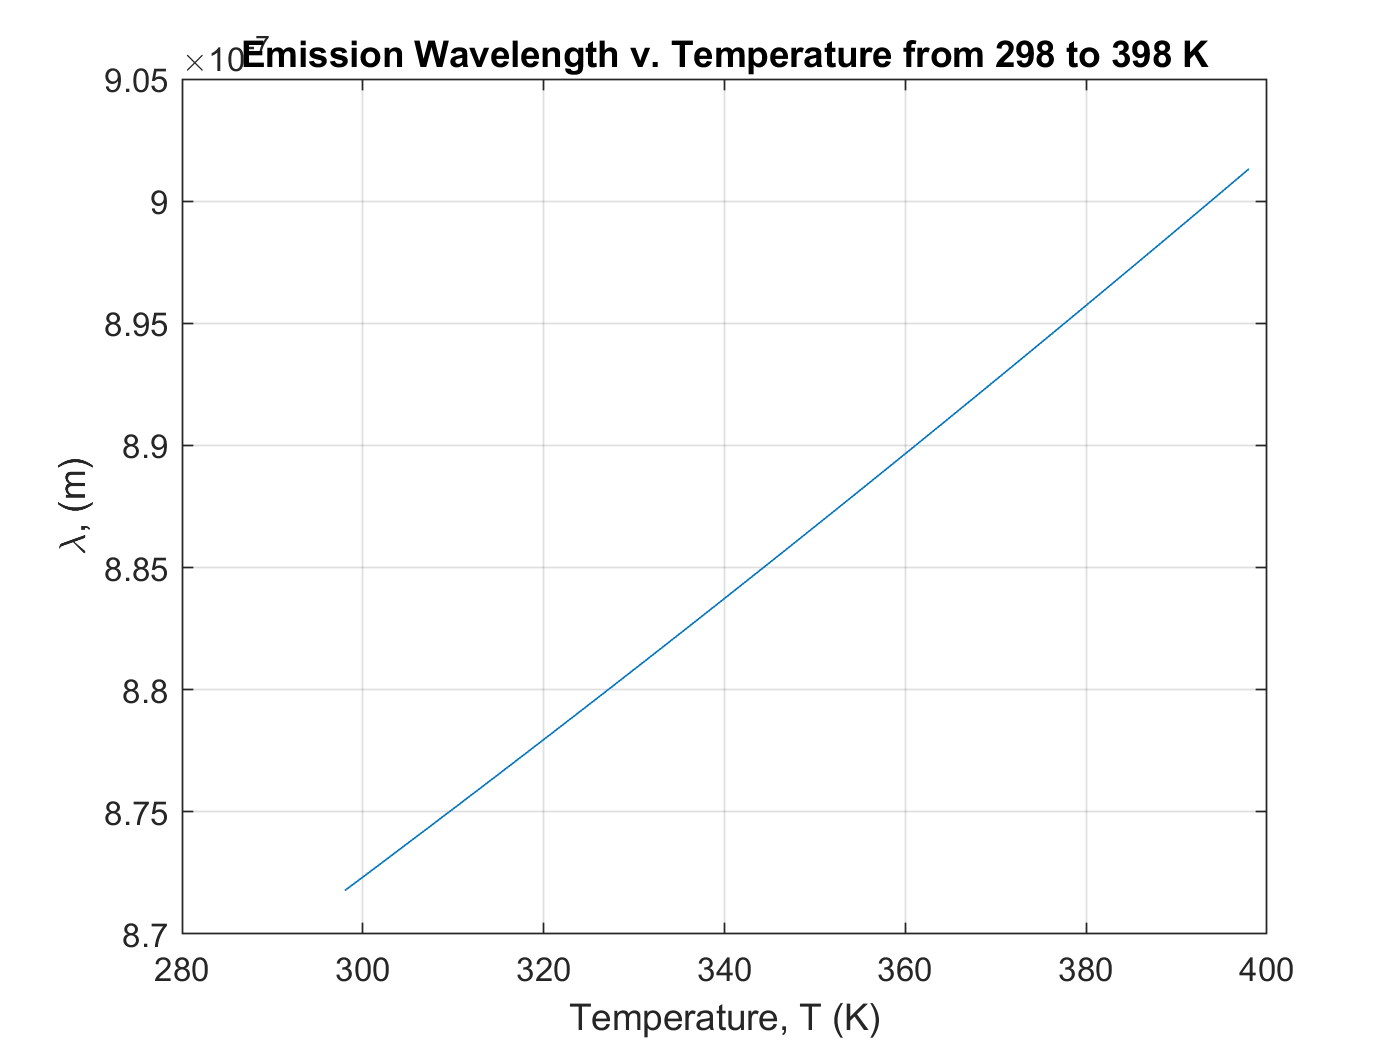

plot(T,lambdaBg)
xlabel('Temperature, T (K)')
ylabel('\lambda, (m)')
title('Emission Wavelength v. Temperature from 298 to 398 K')
grid on


% Part c)
% - Peak emission occurs at Eg + .5*k*T
lambda0 = (h*c)./(Eg + .5*k*T)

lambda0 = 	1.0e+-6 *

    0.8640    0.8642    0.8645    0.8647    0.8650    0.8652    0.8655    0.8657    0.8660    0.8662    0.8665    0.8667    0.8670    0.8672    0.8675    0.8677    0.8680    0.8682    0.8685    0.8687    0.8690    0.8692    0.8695    0.8697    0.8700    0.8702    0.8705    0.8707    0.8710    0.8713    0.8715    0.8718    0.8720    0.8723    0.8725    0.8728    0.8731    0.8733    0.8736    0.8738    0.8741    0.8744    0.8746    0.8749    0.8751    0.8754    0.8757    0.8759    0.8762    0.8764


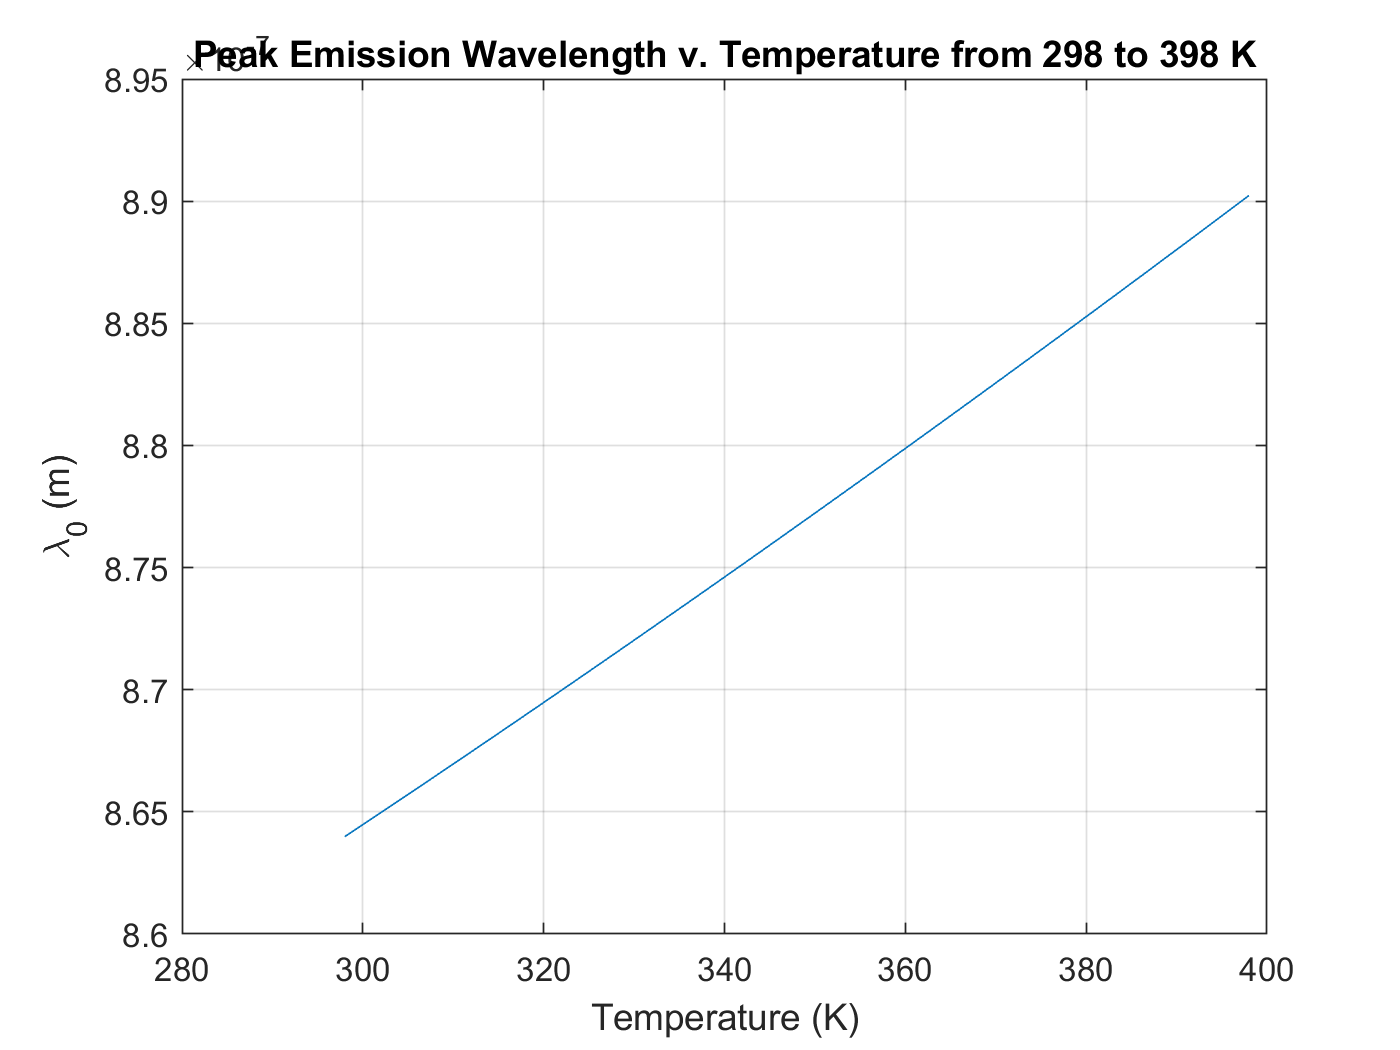

plot(T,lambda0)
xlabel('Temperature (K)')
ylabel('\lambda_0 (m)')
title('Peak Emission Wavelength v. Temperature from 298 to 398 K')
grid on;


% Thoughts regarding b) and c): It makes sense that Emission wavelength has the same
% relationship to temperature as the 'Peak' Emission wavelength.  It is
% slightly greater than the Peak for a given T since Peak Emessions have higher 
% thus a smaller wavelength

% Part d)
lambda0298 = lambda0(1)

lambda0298 = 8.6398e-07

lambda0398 = lambda0(101)

lambda0398 = 8.9023e-07

lw298 = ((lambda0298^2)/(h*c))*3*k*298

lw298 = 4.6347e-08

lw398 = ((lambda0398^2)/(h*c))*3*k*398

lw398 = 6.5717e-08